### Driving towards april tag behaviors

clear all
clear


% Connect to raspi
    robotPi = raspi('192.168.33.177', 'pi', 'raspberry');
    roverServos = I2C_Servo_pHAT(robotPi);

% Create connection to the V2 Pi Camera
    robotCam = cameraboard(robotPi, 'Resolution', '1280x720'); 
    robotCam.ExposureMode = 'sports';
    robotCam.AWBMode = 'fluorescent';

% Raise payload arm
    roverServos.setServoPWM(3,30);

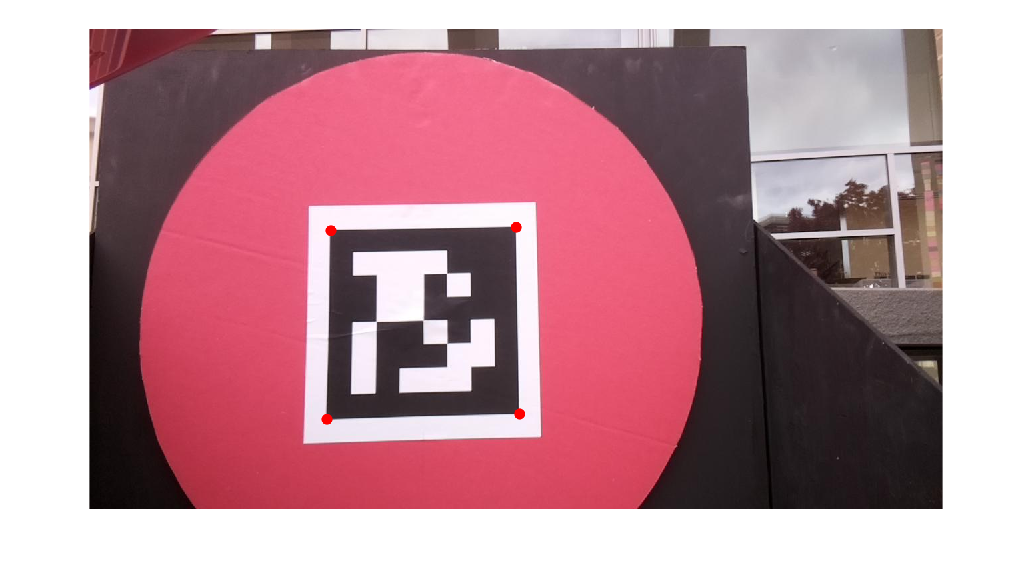

tagSize = 0.1720

for v = 0:1:5
    % Take a photo using the camera
   I = snapshot(robotCam);
end
    
% Display image
figure
[centers, ids, loc, pose] = detectAprilTags(I, 1, "dock");

pose.Translation(1)

ans = 0.2075

pose.Translation(3)

ans = 1.6572

%2.4 distance for payload
%5.76 for dock


### **Code for docking and payload**

controlvar = "dock"

controlvar = "dock"

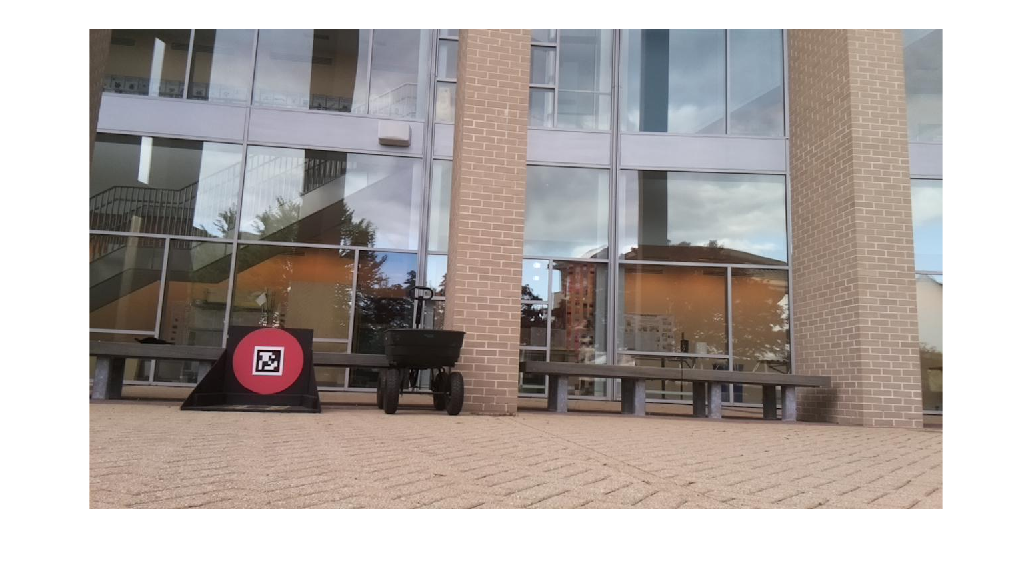

tagSize = 0.1720

april tags found


dist_xpos = 0.5200

dist_location = 13.0216

steering left


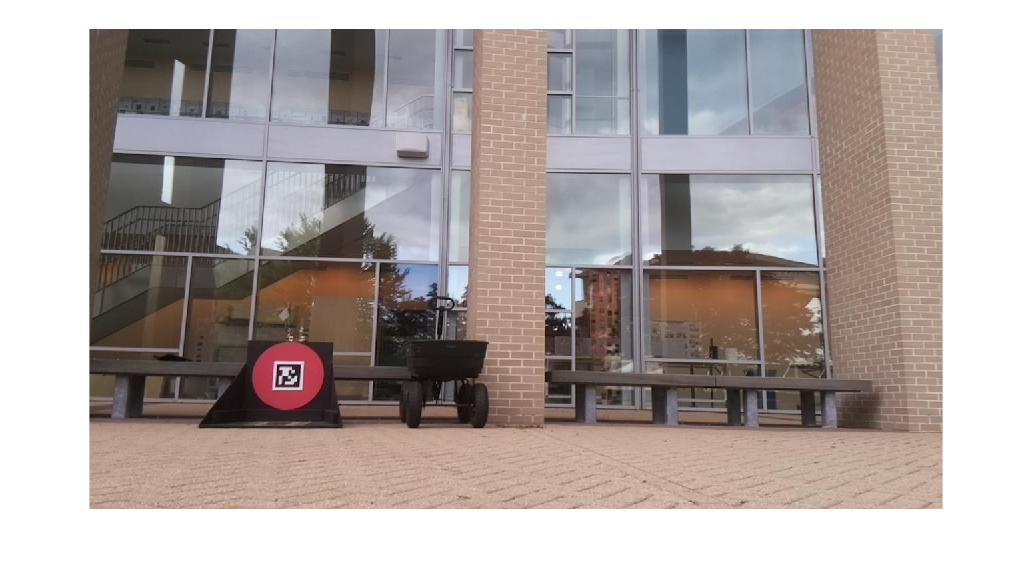

tagSize = 0.1720

april tags found


dist_xpos = 0.6595

dist_location = 12.9414

steering left


tagSize = 0.1720

april tags found


dist_xpos = 0.8105

dist_location = 12.0552

steering left


tagSize = 0.1720

april tags found


dist_xpos = 0.9511

dist_location = 10.6133

steering left


tagSize = 0.1720

april tags found


dist_xpos = 1.0227

dist_location = 9.3167

steering left


tagSize = 0.1720

april tags found


dist_xpos = 1.0372

dist_location = 8.4547

steering left


tagSize = 0.1720

april tags found


dist_xpos = 1.0352

dist_location = 7.3878

steering left


tagSize = 0.1720

april tags found


dist_xpos = 0.9873

dist_location = 6.1721

steering left


tagSize = 0.1720

april tags found


dist_xpos = 0.7196

dist_location = 3.0272

steering right


tagSize = 0.1720

april tags found


dist_xpos = 0.5700

dist_location = 1.9431

steering right


tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


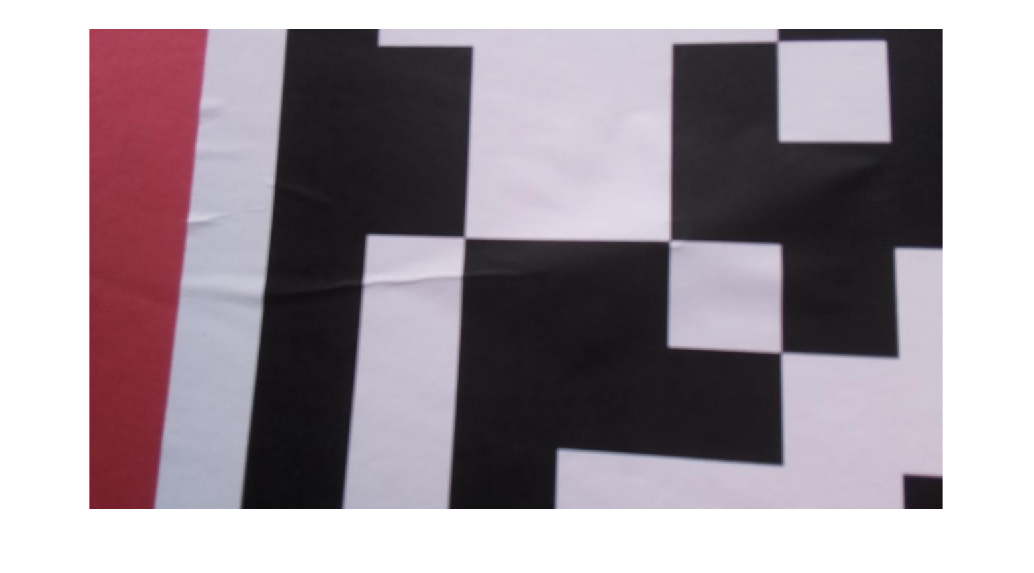

tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


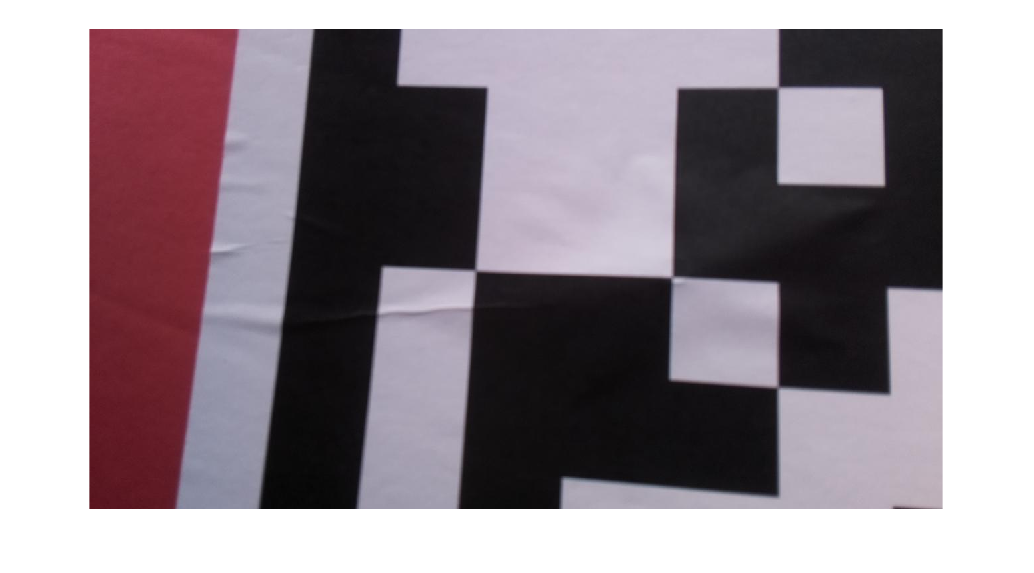

tagSize = 0.1720

no april tags found


stopping, no tag found


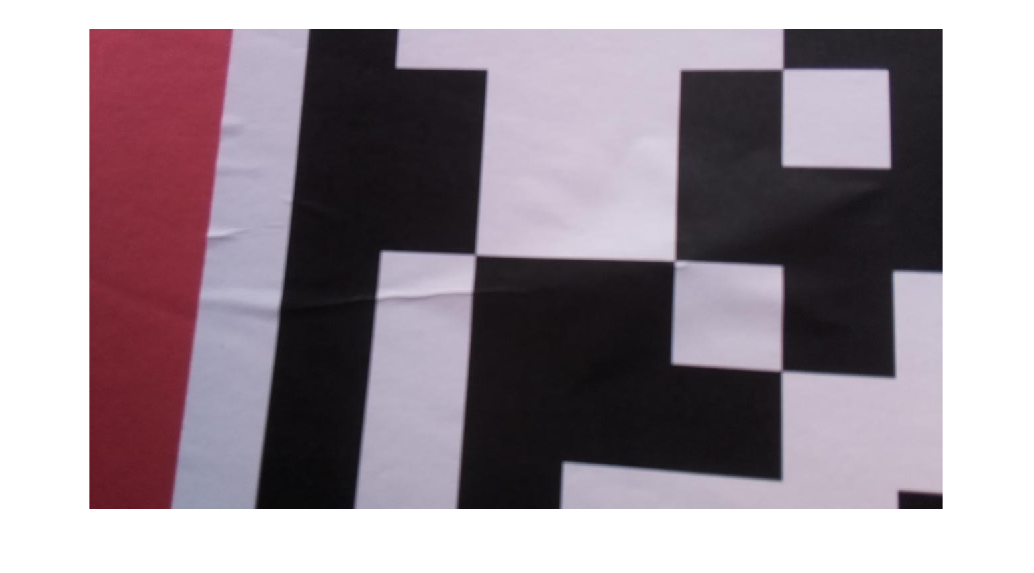

tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


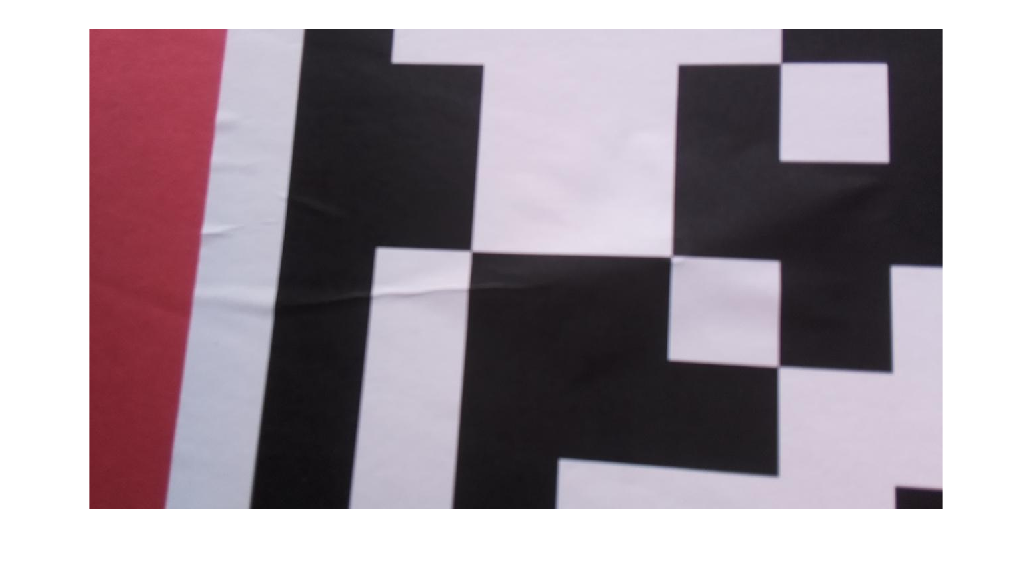

tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


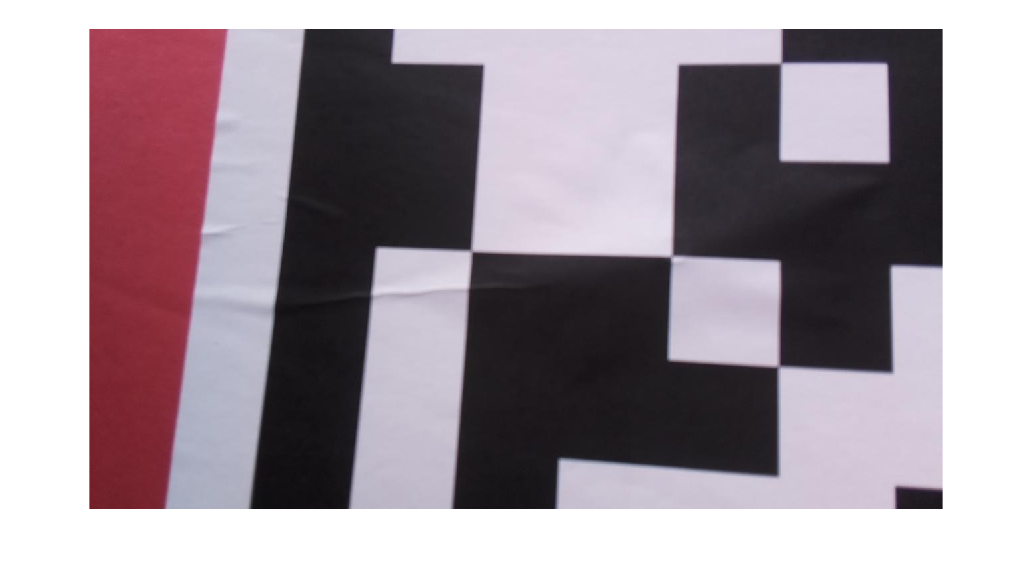

tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


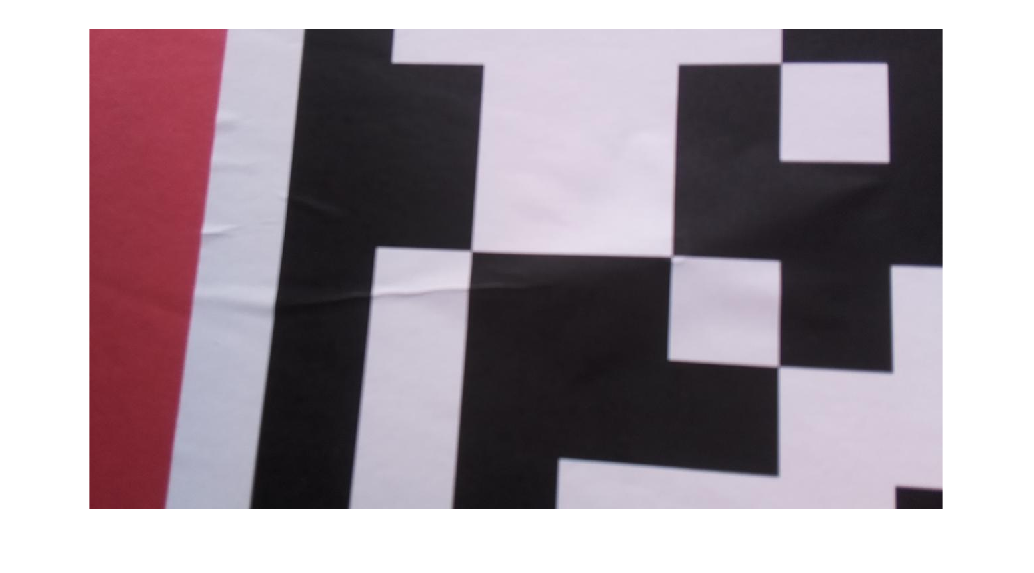

tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


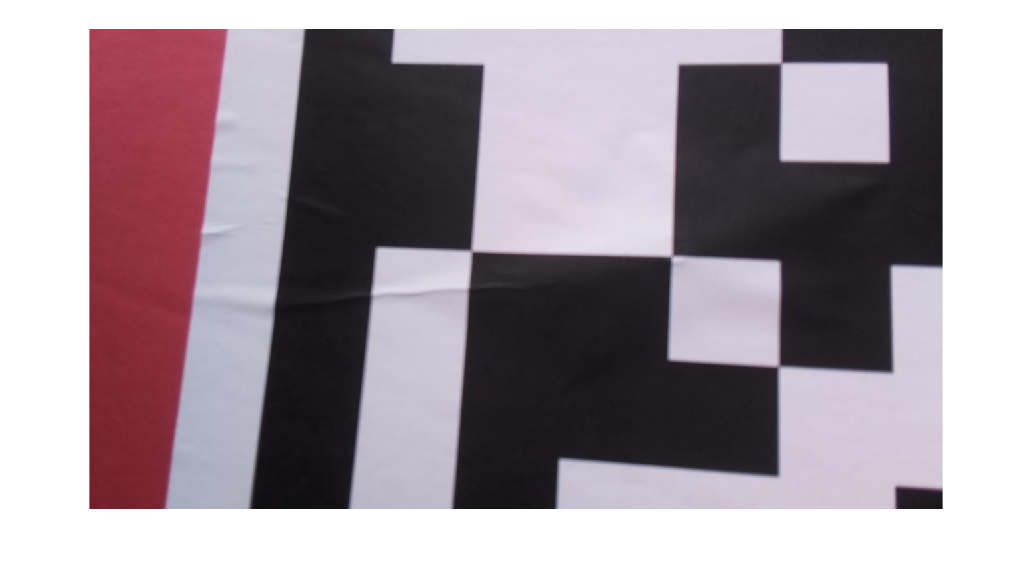

tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


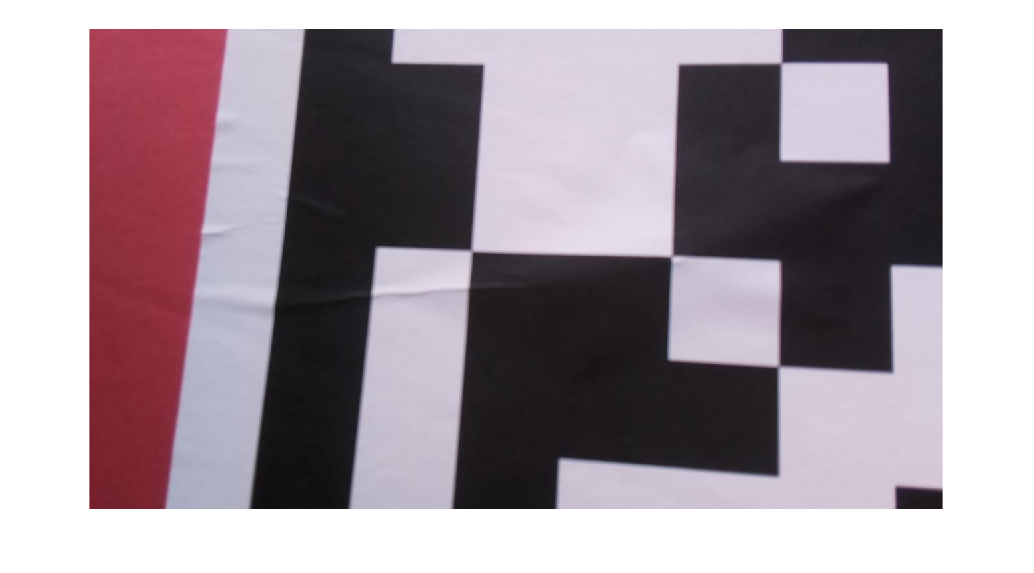

tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


tagSize = 0.1720

no april tags found


stopping, no tag found


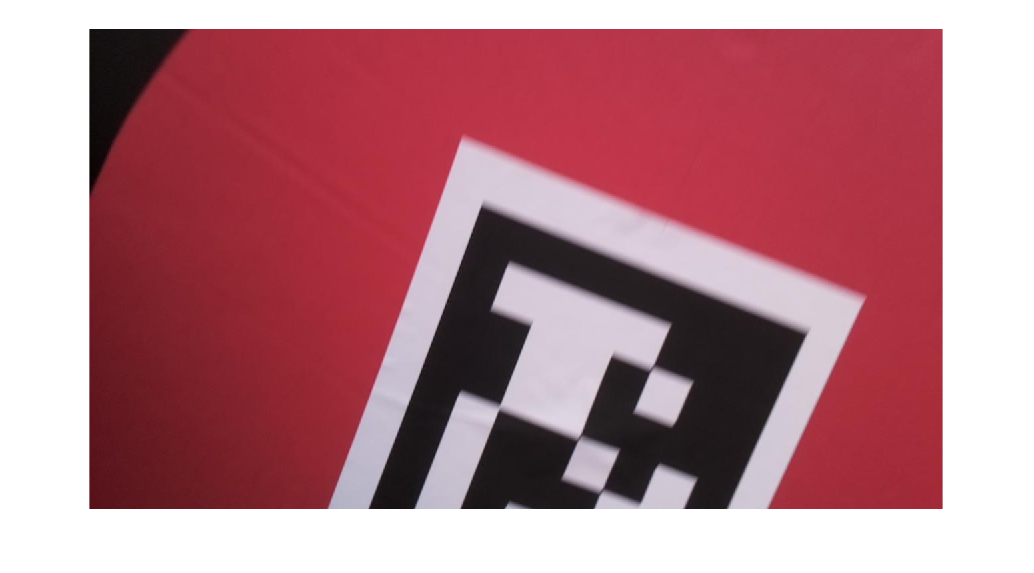

% controlvar = "payload"

% Rover drive speed
speed = 45;



if controlvar == "dock"
    roverServos.setServoPWM(3,0);
    stop_dist = 1.5;
    extra_drivetime = 0;
elseif controlvar == "payload"
    roverServos.setServoPWM(3,30);
    extra_drivetime = 0.83;
    stop_dist = 3;
end


far =1;
tic
while far
    
    % Take photos
    for v = 0:1:3
       I = snapshot(robotCam);
    end
    
    % Display image
    figure, imshow(I)
    [centers, ids, loc, pose] = detectAprilTags(I, false, controlvar);
  
    % If april tags are found
    if isempty(ids)==0
        disp("april tags found")
        dist_xpos = pose.Translation(1)
        dist_location =  pose.Translation(3)    
        
          % Drive towards april tag
        if checkdirection(centers) == "right"
%         if CheckPosePosition(dist_xpos) == "right"
            % Steer to right
            disp("steering right")
            bearing = 5;  %degrees
            DriveRover(roverServos,bearing, speed);
        else
            % Steer to left
            disp("steering left")
            bearing = -5;   %degrees
            DriveRover(roverServos,bearing, speed);
        end

        if dist_location < stop_dist
            disp("april tag too close, exiting loop")
            far = 0;
        end
        
    else
            disp("no april tags found")
            DriveRover(roverServos,2, 0);
            disp("stopping, no tag found")
    end

end


disp("end of while loop")
disp("driving for extra drive time")
pause(extra_drivetime)
DriveRover(roverServos,2, 0);

if controlvar == "payload"
    disp("deploying payload")
    roverServos.setServoPWM(3,1);
end


** Code for payload**


roverServos.setServoPWM(3,30);
extra_drivetime = 0.83;
far =1;
while far == 1
    % Flush camera buffer
    for v = 0:1:5
        % Take a photo using the camera
       I = snapshot(robotCam);
    end
    
    % Display image
    figure, imshow(I)
    [centers, ids, loc, pose] = detectAprilTags(I, false, "payload")
    pose.Translation(3)    
    % Rover drive speed
    speed = 45;
    % If april tags are found
    if isempty(ids)==0
        disp("april tags found")
        
        % Drive towards april tag
        if checkdirection(centers) == "right"
            % Steer to right
            disp("steering right")
            bearing = 7;  %degrees
            DriveRover(roverServos,bearing, speed);
        else
            % Steer to left
            disp("steering left")
            bearing = -7;   %degrees
            DriveRover(roverServos,bearing, speed);
        end
        
        % If april tag is very close, stop rover
%         scatter(loc(:,1), loc(:,2))
        [k, area] = boundary(loc(:,1), loc(:,2));
        area
        if area > (15000)
            disp("april tag too close, exiting loop")
            far = 0;
        end
    else
            disp("no april tags found")
    end

end

pause(extra_drivetime)
DriveRover(roverServos,2, 0);
disp("tag perfect, rover stopped")

disp("deploying payload")
roverServos.setServoPWM(3,1);


### Testing april tag function with just one picture

% I = imread("april_tag_5_5.jpg");
% [centers, ids, loc] = detectAprilTags(I, true) % Change to false to suppress output
% 
% % I = imread("no_april_tag.jpg");
% % [centers, ids, loc] = detectAprilTags(I, true) % Change to false to suppress output
% 
% %TODO: TEST WHAT HAPPENS WITH MULTIPLE APRIL TAGS
% 
% % Rover drive speed
% speed = 45;
% % if april tags are found
% if isempty(ids)==0
%     disp("april tags found")
%     
%     % drive towards april tag
%     if checkdirection(centers) == "right"
%         %steer to right
%         disp("steering right")
%         bearing = 15;  %degrees
% %         DriveRover(robotPi,roverServos,bearing, speed);
%     else
%         %steer to left
%         disp("steering left")
%         bearing = -15;   %degrees
% %         DriveRover(robotPi,roverServos,bearing, speed);
%     end
%     
%     % check how close the april tags are and stop when super close
% %     scatter(loc(:,1), loc(:,2))
%     [k, area] = boundary(loc(:,1), loc(:,2))
%     if area > (750*1334*0.6)
%         disp("april tag too close, stopping rover")
% %         DriveRover(robotPi,roverServos,0, 0);
%     end
% else
%     disp("no april tags found")
% end


function [centers, ids, loc, pose] = detectAprilTags(image, display, payloadOrDock)
    tagFamily = ["tag36h11"];
    
    focalLength = [2714.3 2714.3];
    principlePoint = [160, 120];
    imageSize = [240, 320];
    intrinsics = cameraIntrinsics(focalLength, principlePoint, imageSize);
    
    if payloadOrDock == "payload"
        tagSize = 0.1135 % payload;
    elseif payloadOrDock == "dock"
        tagSize = .172 %dock;
    end
    
    [ids,loc,pose] = readAprilTag(image, tagFamily, intrinsics, tagSize);
    centers = zeros(length(ids), 2);
    for idx = 1:length(ids)
        % Compute center of tag
        center = mean(loc(:,:,idx));

        % Add 2D center of tag to list
        centers(idx,:) = center;
        
        if display
            % Display the ID and tag family
%             disp("Detected Tag ID: " + ids(idx))
%             disp("Location: " +loc)
%             disp(pose)
            % Insert markers to indicate the locations
            markerRadius = 8;
            numCorners = size(loc,1);
            markerPosition = [loc(:,:,idx),repmat(markerRadius,numCorners,1)];
            image = insertShape(image,"FilledCircle",markerPosition,"Color","red","Opacity",1);

        end
    end
    
    if display
        imshow(image);
    end
end

function[direction] = CheckPosePosition(apriltagxposn)
    if apriltagxposn > 0.5 %if x point is to the right
        direction = "right" 
    end
    
    if apriltagxposn <= 0.5
        direction = "left"     
    end

end

function [direction] = checkdirection(apriltag_centroid)
    camera_horizontal_centroid = 1334/2;
    apriltag_horizontal_centroid = apriltag_centroid(1);
    
    % april tag on the left
    if (apriltag_horizontal_centroid < camera_horizontal_centroid)
        direction = "left";

    end
    % april tag on the right
    if (apriltag_horizontal_centroid > camera_horizontal_centroid)
        direction = "right";
    end
end

ACT


function pwm = AngleForServo(angle)
pwm = ((angle + 85.21)/1.755) - 2.35;
pwm = pwm(1);
end

function [] = DriveRover(roverServos,direction,speed)
    roverServos.setServoPWM(1,AngleForServo(direction));    % commands steering servo
    roverServos.setServoPWM(2,speed);    % commands drive speed controller
end

